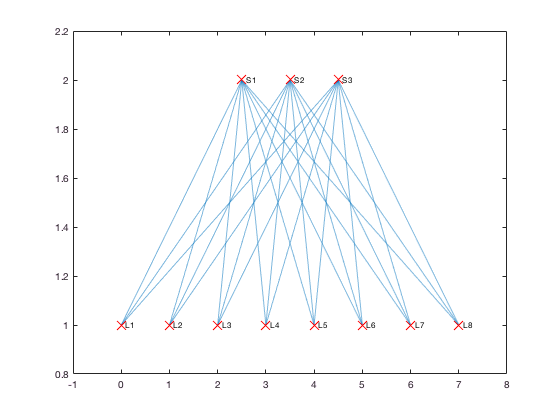

Elapsed time is 0.362546 seconds.


G=graphTopology(false,false,'SpineLeaf',3,8,2);
p=plotGraphtopology(G);

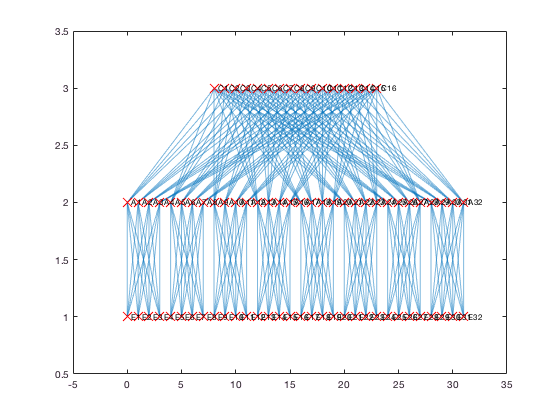

Elapsed time is 1.065192 seconds.


G=graphTopology(false,false,'Portland',8);
p=plotGraphtopology(G);

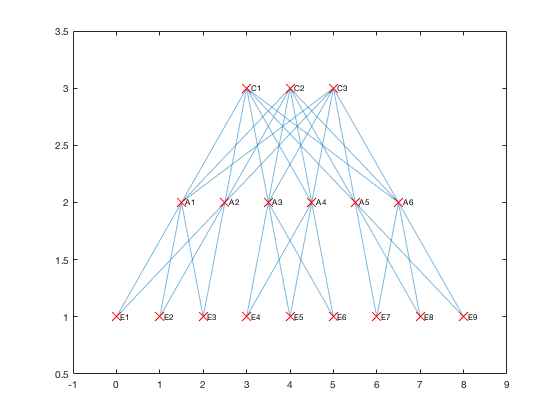

Elapsed time is 0.374089 seconds.


You selected case #1, a 4x4 network:
   Inf     1   Inf     1
     1   Inf     1     1
   Inf     1   Inf   Inf
   Inf   Inf   Inf   Inf

The path request is from source node 3 to destination node 4, with K = 5 

Result of Function call: kShortestPath(netCostMatrix, source, destination, k)  = 

Path # 1:
     3     2     4

Cost of path 1 is  2.00

Path # 2:
     3     2     1     4

Cost of path 2 is  3.00



ans = 18×1 cell array
    'C1'
    'C2'
    'C3'
    'A1'
    'A2'
    'A3'
    'A4'
    'A5'
    'A6'
    'E1'
    'E2'
    'E3'
    'E4'
    'E5'
    'E6'
    'E7'
    'E8'
    'E9'


G=graphTopology(false,false,'VL2',6);
p=plotGraphtopology(G);

source=findnode(G,'C1');
dest=findnode(G,'C2');
[paths, cost]=kshortestpathsx(G,[source dest],3,'unweight');
disp(paths{1,1}{1,1})

     1     4     2



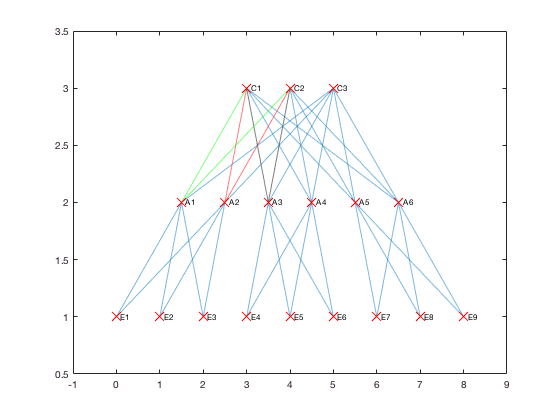

highlight(p,paths{1,1}{1,1},'EdgeColor','g')
highlight(p,paths{1,1}{1,2},'EdgeColor','r')
highlight(p,paths{1,1}{1,3},'EdgeColor','k')